# Tutorial 8 - Simulate a Multilayer Pouch Cell

## Introduction

In this tutorial, we simulate a multilayer pouch cell. We use the same material property as in the other tutorials

jsonstruct_material = parseBattmoJson('Examples/jsondatafiles/sample_input.json');

Next, we load and parse a json file where we have chosen some parameters for the multilayer pouch domain. Note that all the parameters are described in a json schema, see [Geometry.schema.json](https://github.com/BattMoTeam/BattMo/blob/dev/Utilities/JsonSchemas/Geometry.schema.json), even if the simplest way to proceed is to start with an example, in this case given by [geometryMultiLayerPouch.json](https://github.com/BattMoTeam/BattMo/blob/dev/Examples/JsonDataFiles/geometryMultiLayerPouch.json).

jsonfilename = 'Examples/JsonDataFiles/geometryMultiLayerPouch.json';
jsonstruct_geometry = parseBattmoJson(jsonfilename);

We use [FlatJsonViewer.m](https://github.com/BattMoTeam/BattMo/blob/dev/Utilities/JsonUtils/FlatJsonViewer.m) to flatten the json structure and print it to screen. We can see that, in this example, we use 5 layers and two different lengths for the tabs (height value). At the moment, the two tabs share the same width. Implementing a separate width for each tab would require to modify the grid generator for this geometry. It is more a developper work but is definitely not out of reach.

fjv = flattenJson(jsonstruct_geometry)

fjv =   FlatJsonViewer with properties:

       flatjson: {23x2 cell}
    columnnames: {'parameter name'  'parameter value'}


fjv.print();

ans = 23x2 table
                     parameter name                       parameter value  
    ________________________________________________    ___________________

    {'Geometry.case'                               }    {'multiLayerPouch'}
    {'Geometry.nLayers'                            }    {[              5]}
    {'Geometry.width'                              }    {[         0.1000]}
    {'Geometry.height'                             }    {[         0.1000]}
    {'Geometry.tab.width'                          }    {[         0.0500]}
    {'Geometry.tab.Nx'                             }    {[              3]}
    {'Geometry.tab.NegativeElectrode.height'       }    {[         0.0400]}
    {'Geometry.tab.NegativeElectrode.Ny'           }    {[              2]}
    {'Geometry.tab.PositiveElectrode.height'       }    {[         0.0200]}
    {'Geometry.tab.PositiveElectrode.Ny'           }    {[              2]}
    {'Geometry.Electrolyte.Nx'                     }    {[            

We load and parse the control protocol

jsonfilename = fullfile('Examples', 'jsondatafiles', 'cc_discharge_control.json');
jsonstruct_control = parseBattmoJson(jsonfilename);

We load and parse the simulation settings. This is optional. Typically, reasonable choices are made by default.

jsonfilename = fullfile('Examples', 'jsondatafiles', 'simulation_parameters.json');
jsonstruct_simparams = parseBattmoJson(jsonfilename);

Now, we can merge these parameter definitions into a single parameter set to obtain a jsonstruct that has all the input needed by the simulator.

jsonstruct = mergeJsonStructs({jsonstruct_geometry , ...
                               jsonstruct_material , ...
                               jsonstruct_control  , ...
                               jsonstruct_simparams});

parameter include_current_collectors is assigned twice with different values. we use the value from first jsonstruct.
parameter Geometry.case is assigned twice with different values. we use the value from first jsonstruct.
parameter NegativeElectrode.Coating.thickness is assigned twice with different values. we use the value from first jsonstruct.
parameter NegativeElectrode.Coating.N is assigned twice with different values. we use the value from first jsonstruct.
parameter NegativeElectrode.CurrentCollector.N is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.thickness is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.N is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.CurrentCollector.N is assigned twice with different values. we use the value from first jsonstruct.
parameter Separator.thickness

## Setup the model for inspection

When we run the simulation using function [runBatteryJson.m](https://github.com/BattMoTeam/BattMo/blob/dev/Examples/JsonInput/runBatteryJson.m), the model is setup. In the case where we want to setup the model for inspection, prior to simulation, we can use the function [setupModelFromJson.m](https://github.com/BattMoTeam/BattMo/blob/dev/Utilities/JsonUtils/setupModelFromJson.m)

model = setupModelFromJson(jsonstruct);

We use the [plotBatteryGrid.m](https://github.com/BattMoTeam/BattMo/blob/dev/Utilities/Visualization/plotBatteryGrid.m) function to show the grid

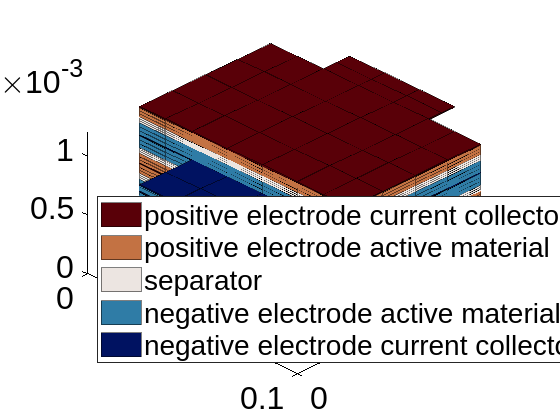

plotBatteryGrid(model)
% make the axis tight and set the camera viewing angle
axis tight
view(45,45)

## Run the simulation

output = runBatteryJson(jsonstruct);

## Visualize the Results

extract the time and voltage quantities

states = output.states;

time    = cellfun(@(state) state.time, states);
voltage = cellfun(@(state) state.('Control').E, states);

We plot the discharge curves together in a new figure

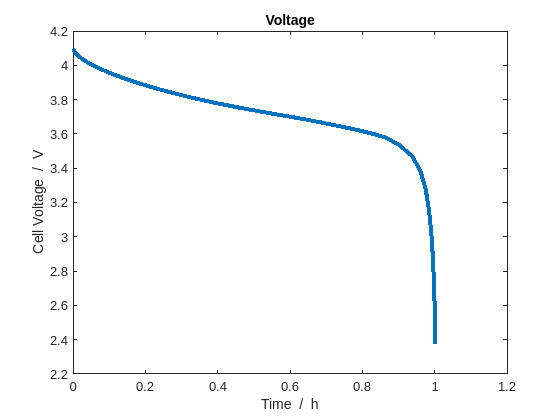

figure();
plot((time/hour), voltage, '-', 'linewidth', 3)
xlabel('Time  /  h')
ylabel('Cell Voltage  /  V')
title('Voltage');

For a given time step, we plot the concentration on the grid.

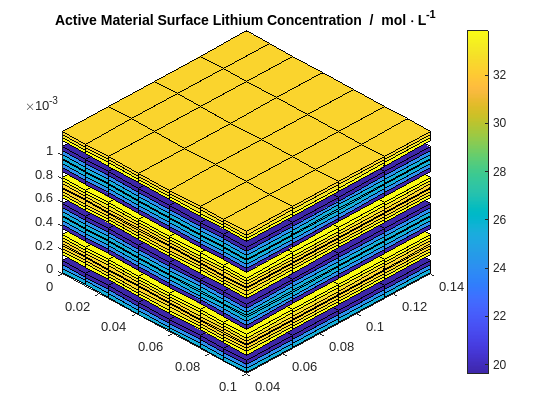

% Set the timestep we want to visualize
timestep = 20;

% get the state of the simulation at the given timestep
state = states{timestep};

% create a new figure
figure()

% plot the surface concentration of lithium in the negative electrode active material
plotCellData(model.NegativeElectrode.Coating.G, state.NegativeElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface/(mol/litre))

% plot the surface concentration of lithium in the positive electrode active material
plotCellData(model.PositiveElectrode.Coating.G, state.PositiveElectrode.Coating.ActiveMaterial.SolidDiffusion.cSurface/(mol/litre))

title('Active Material Surface Lithium Concentration  /  mol \cdot L^{-1}');
% add a colorbar
colorbar()
view(45,45)